# LBYEC3F: PROJECT CODES

Written by: Dayrit, Bettina

## DESIGN CRITERIA:

- Settling Time (Ts) <= 1 second

- Overshoot (%OS) <= 5%

- Steady-state error <= 1%

#### THE ELECTROMECHANICAL SYSTEM (DC MOTOR) IS GIVEN BY THE DIAGRAM

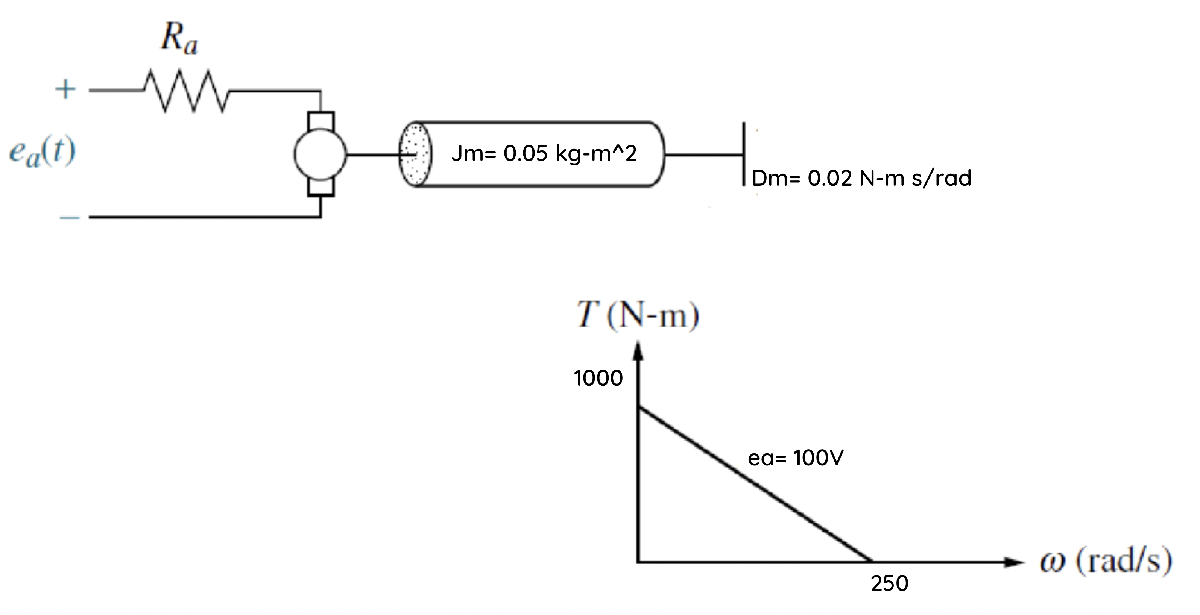

## DETERMINING THE TRANSFER FUNCTION AND INITIAL TIME RESPONSES

In modeling electric motors, its transfer function is given by:

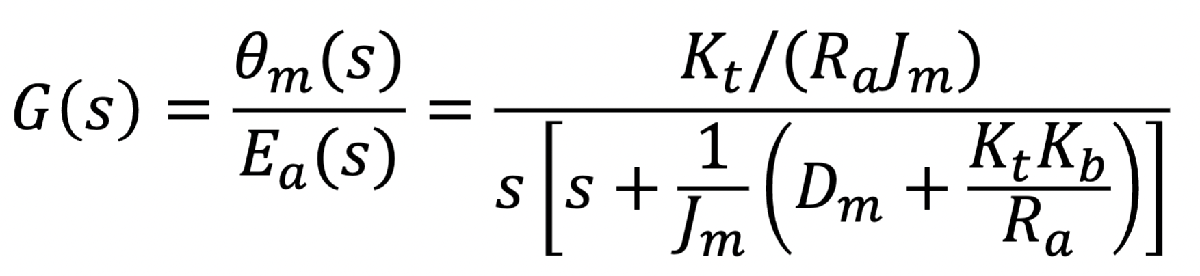

% Assuming the following values of the physical parameters:

Jm= 0.05;
Dm= 0.02;
KtRa= 10;
Kb= 0.4;

% transfer function
num= [KtRa*(1/Jm)];
dena= (1/Jm)*(Dm+(KtRa*Kb));
den= conv([1 0], [1 dena]);
motortf= tf(num, den) 

motortf =
 
      200
  ------------
  s^2 + 80.4 s
 
Continuous-time transfer function.



The given block diagram of the control system is as follows, 

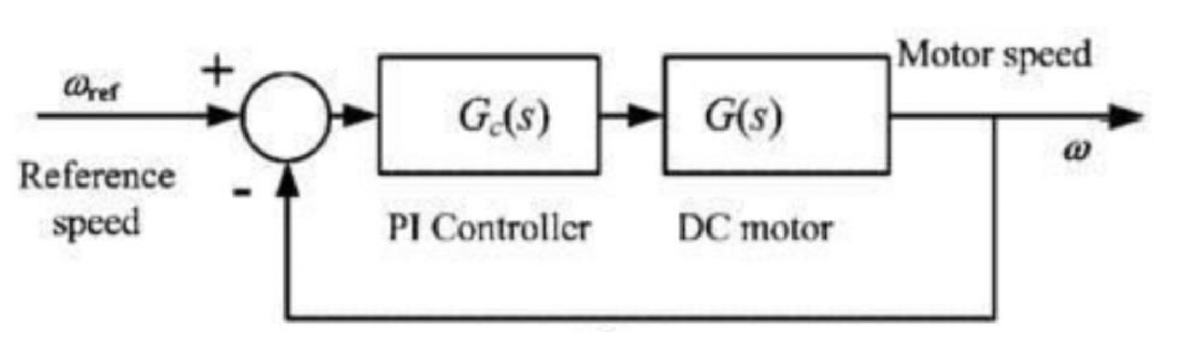

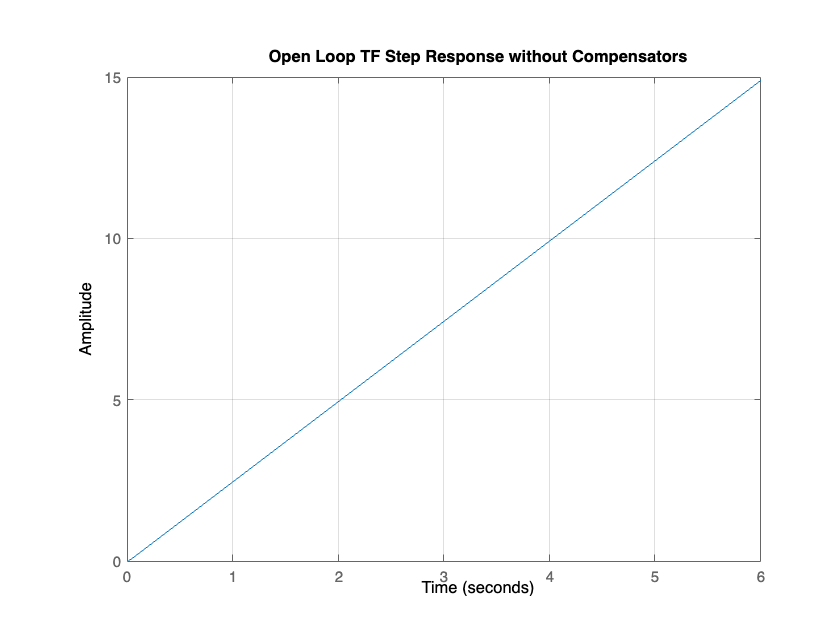

% Open-loop system without any compensators (controller) 
motortf= tf(num, den); 
step(motortf); grid on; title('Open Loop TF Step Response without Compensators')


% Closed-loop, feedback system without any compensators (controller) 
motortf= tf(num, den); 
motortfCL= feedback(motortf, 1) % main G(s)

motortfCL =
 
         200
  ------------------
  s^2 + 80.4 s + 200
 
Continuous-time transfer function.



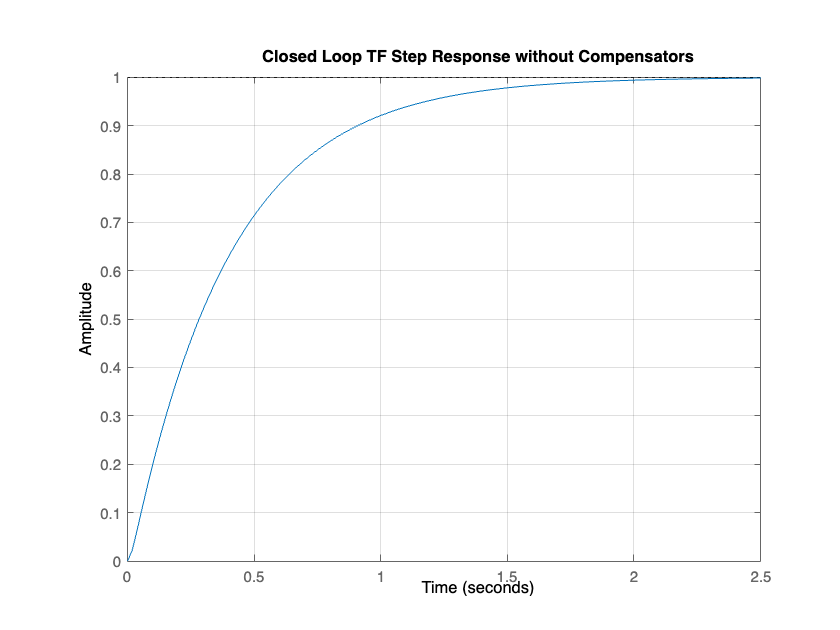

step(motortfCL); grid on; title('Closed Loop TF Step Response without Compensators')

info_mtr= stepinfo(motortfCL)

info_mtr = struct with fields:
         RiseTime: 0.8554
    TransientTime: 1.5355
     SettlingTime: 1.5355
      SettlingMin: 0.9012
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 2.8495



% getting steady-state error
[out, t]= step(motortfCL);
SP= 1;
error= abs(SP-out(end))

error = 0.0031

**== COMMENT:**

From the given step response info: 

- Settling Time= 1.5355 ... does not satisfy condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.0031 ... satisfied condition (<=1)

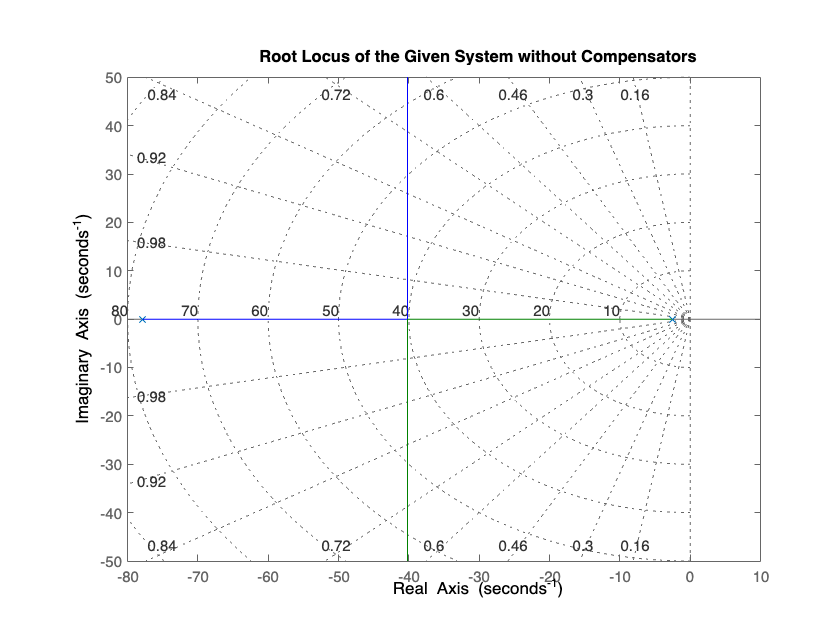

% Root-Locus of the given system without any compensators (controller)
rlocus(motortfCL); grid on; title ('Root Locus of the Given System without Compensators')

**== VISUALIZATIONS:**

From the given root locus of the system: there are two real poles P1= -2.56969 and P2= -77.8303

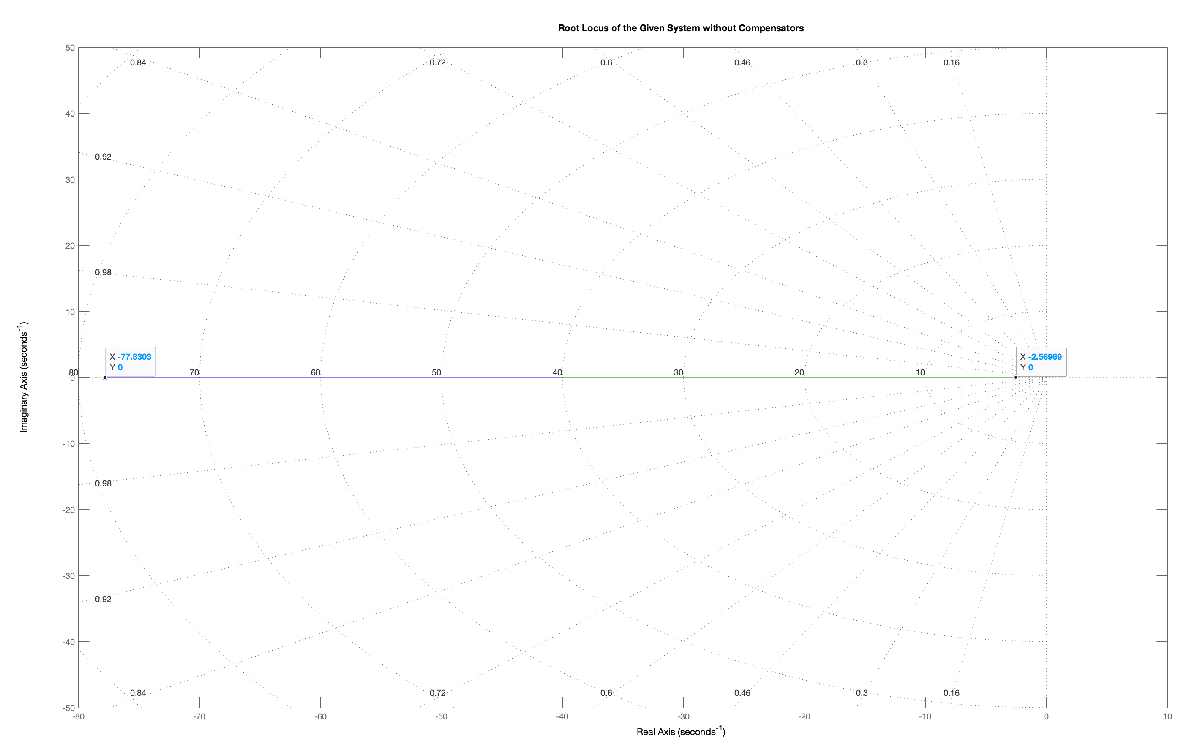

Bode editor using the control system designer, sistool results:

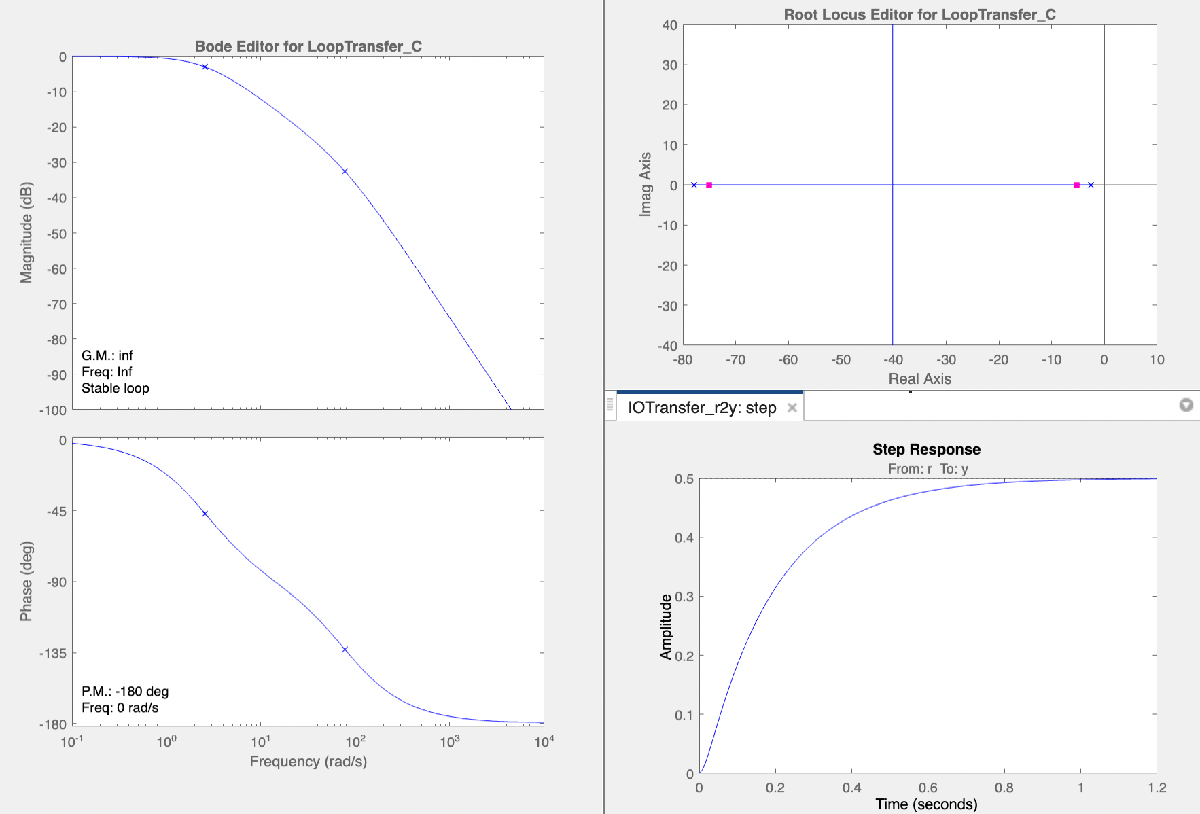

## DETERMINING THE DESIRED POLES

% ... from the given design criteria:
Ts=1;
PO=0.05;
SSE=1;   

zeta= sqrt(log(PO)^2 /(pi^2 + log(PO)^2)) %Damping ratio

zeta = 0.6901

Wn=4/(Ts*zeta) % Natural frequency 

Wn = 5.7962

Incorporating the parameters, the given transfer function is now:

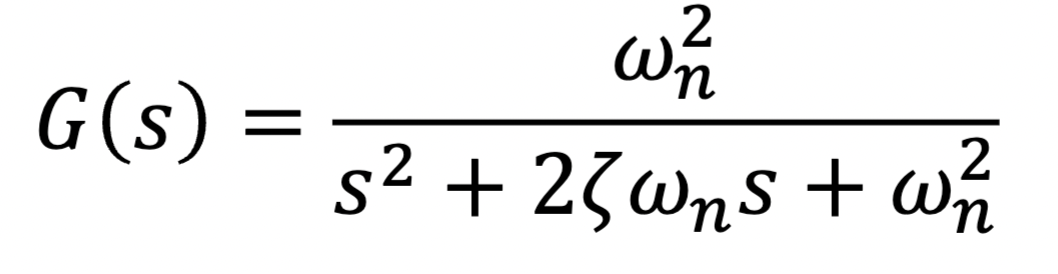

% Computing for the desired poles:
num1= [(Wn)^2];
den1= [1 2*zeta*Wn (Wn)^2];
poles= roots(den1)

poles =   -4.0000 + 4.1948i
  -4.0000 - 4.1948i


**== COMMENT **

Therefore, $S_{1,2\;} =-4\pm 4\ldotp 1948j$ are the desired poles. 

## DESIGNING THE COMPENSATORS  

### Designing a LEAD Compensator 

% Computing for the values of Zlead and Plead, use the method of cancelling
% an existing pole. From the poles as given in the root locus of the given
% system, cancel out P1= -2.56969  

zlead= 2.56969; % this addition of zero will cancel out the pole in -2.56969. 

**== VISUALIZATIONS:**

- A zero placed in the P1= -2.56969 and the desired poles placed accordingly ($-4\pm 4\ldotp 1948j$)

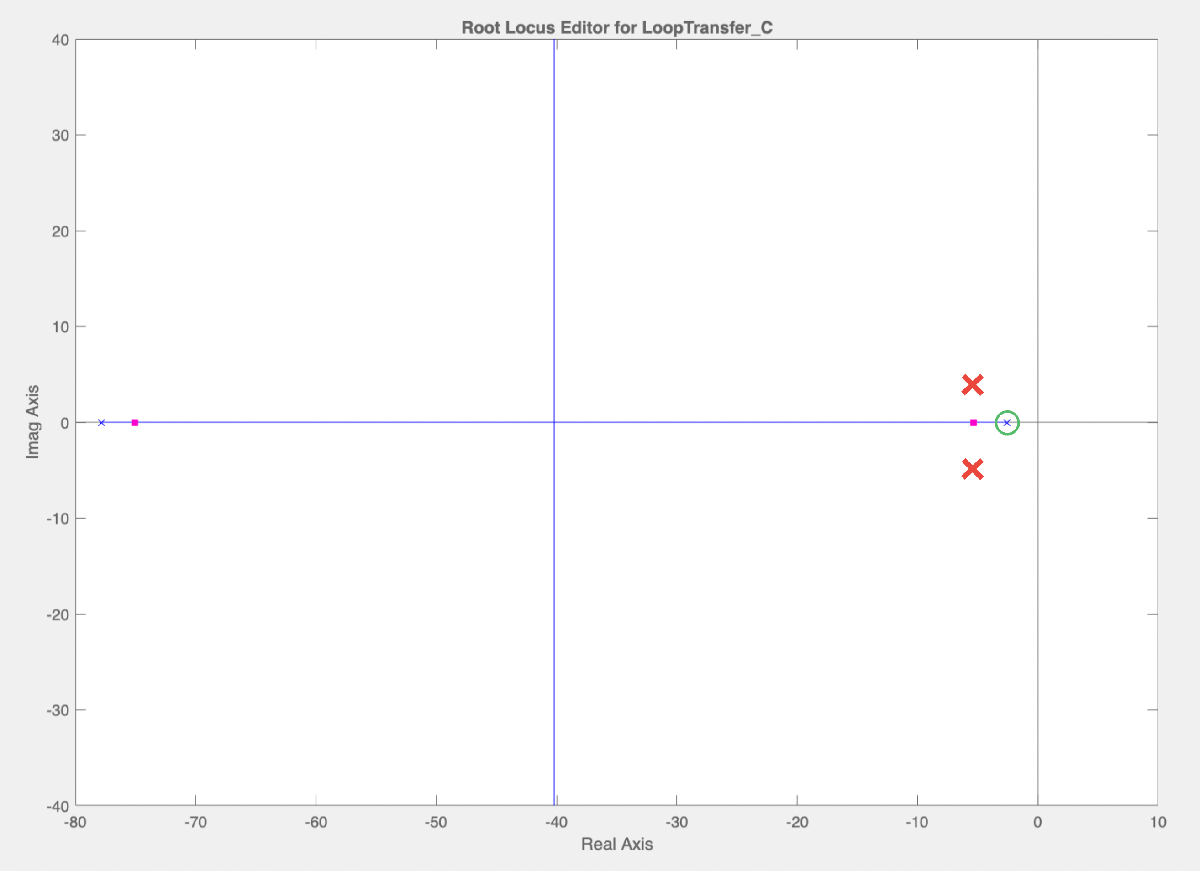

- Graphical method visualization used to compute for the Plead. 

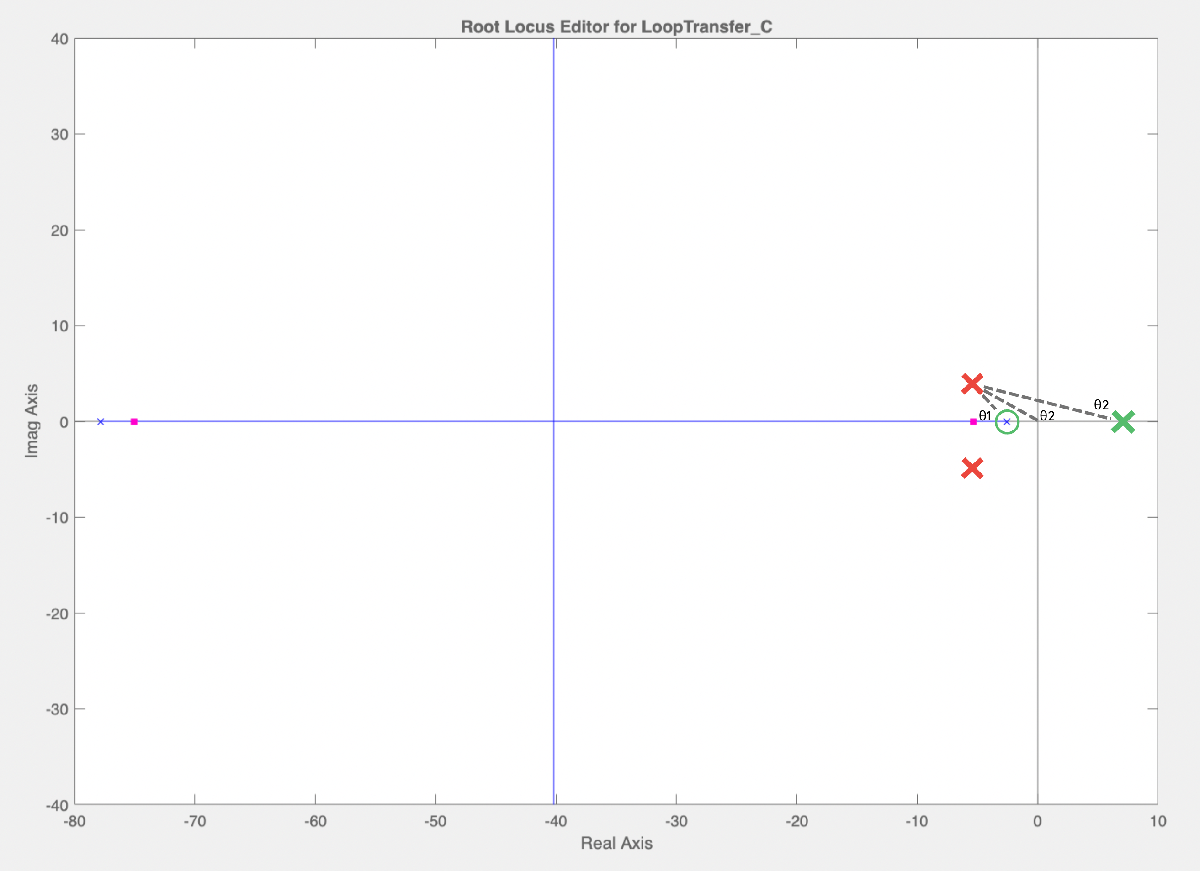

- Graphical method visualization used to compute for the gain. 

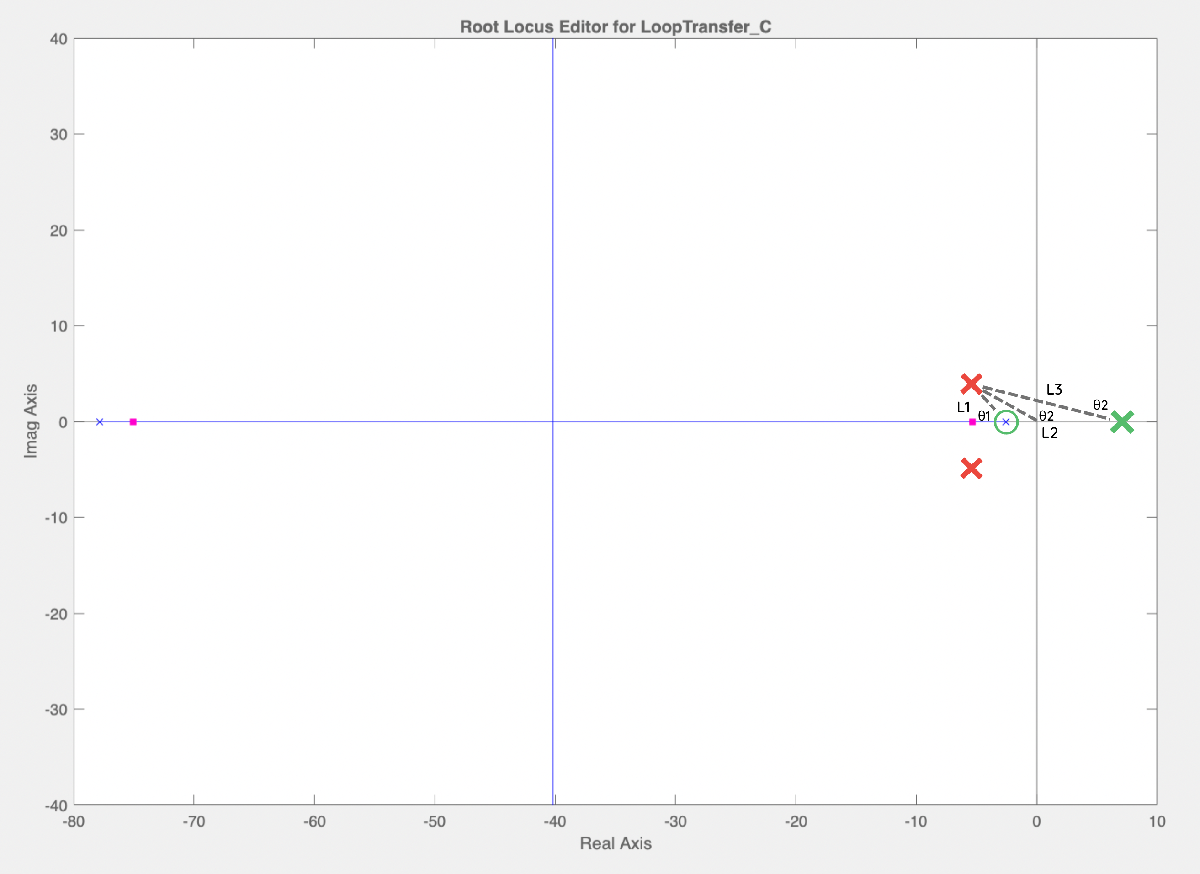

Calculations (formula) for Plead:

θ2 - (θ1+θ2+θ3)= -180

θ1+θ3 = 180

Calculation (formula) for K overall:

K= (L1L2L3/L2)

K= L1L3:

% Solving for θ1 and θ3;
syms plead1

theta1= 180- atan(4.1948/4);
theta3= atan(4.1948/plead1-4);

theta1 + atan(4.1948/plead1-4) == 180

$$ans = \mathrm{atan}\left(\frac{10487}{2500\,{\mathrm{plead}}_{1}}-4\right)+\frac{6304717018494373}{35184372088832}=180$$

plead= 8;

% Solving for K;

L1= sqrt((4.1948)^2 + (4)^2);
L3= sqrt((4.1948)^2 + (4)^2); % the value of 80 came from plead-4 (pole)

K= L1*L3;
overallK= K/200

overallK = 0.1680


% the given transfer function for a lead compensator is:
num2= overallK*[1 zlead];
den2= [1 plead];
LDCtf= tf(num2, den2)

LDCtf =
 
  0.168 s + 0.4317
  ----------------
       s + 8
 
Continuous-time transfer function.




numLDC= conv([200], num2);
denLDC= conv([1 80.4 200], den2);
motortfLDC= tf(numLDC, denLDC) % transfer function of the system compensated using a lead controller

motortfLDC =
 
          33.6 s + 86.33
  -------------------------------
  s^3 + 88.4 s^2 + 843.2 s + 1600
 
Continuous-time transfer function.



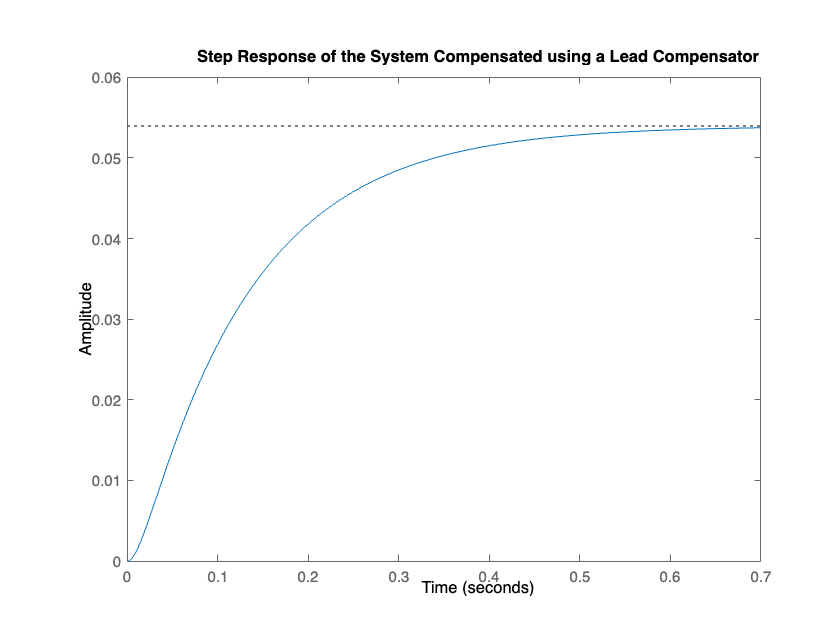


figure (1);
step(motortfLDC); title('Step Response of the System Compensated using a Lead Compensator');

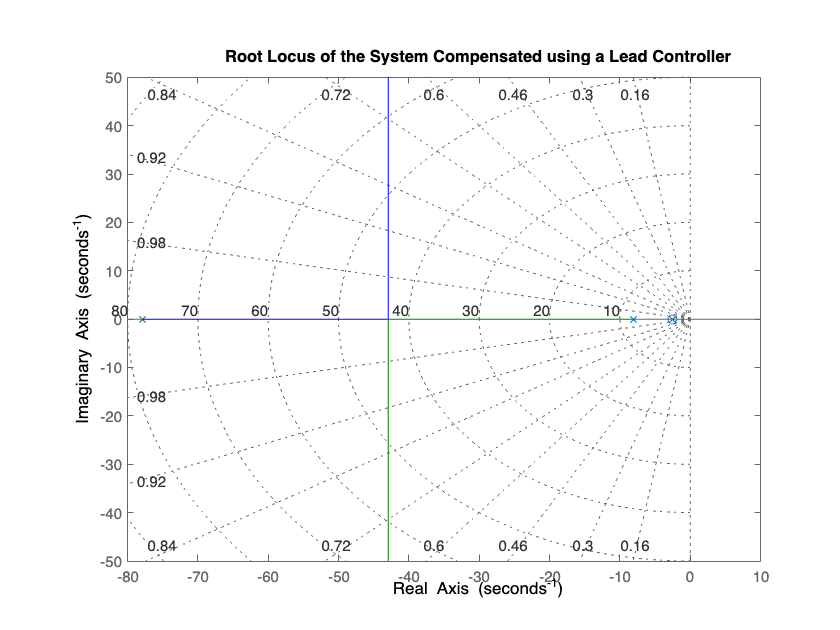

rlocus(motortfLDC); grid on; title('Root Locus of the System Compensated using a Lead Controller');

info_motorLDC= stepinfo(motortfLDC)

info_motorLDC = struct with fields:
         RiseTime: 0.2770
    TransientTime: 0.5026
     SettlingTime: 0.5026
      SettlingMin: 0.0486
      SettlingMax: 0.0539
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0539
         PeakTime: 0.8035


[out1, t1]= step(motortfLDC);
SP= 1;
errorLDC= abs(SP-out1(end))

errorLDC = 0.9463

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.5026 ... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.9463 ...satisfied condition  (<=1)

**== VISUALIZATION:**

Bode editor using the control system designer, sistool results:

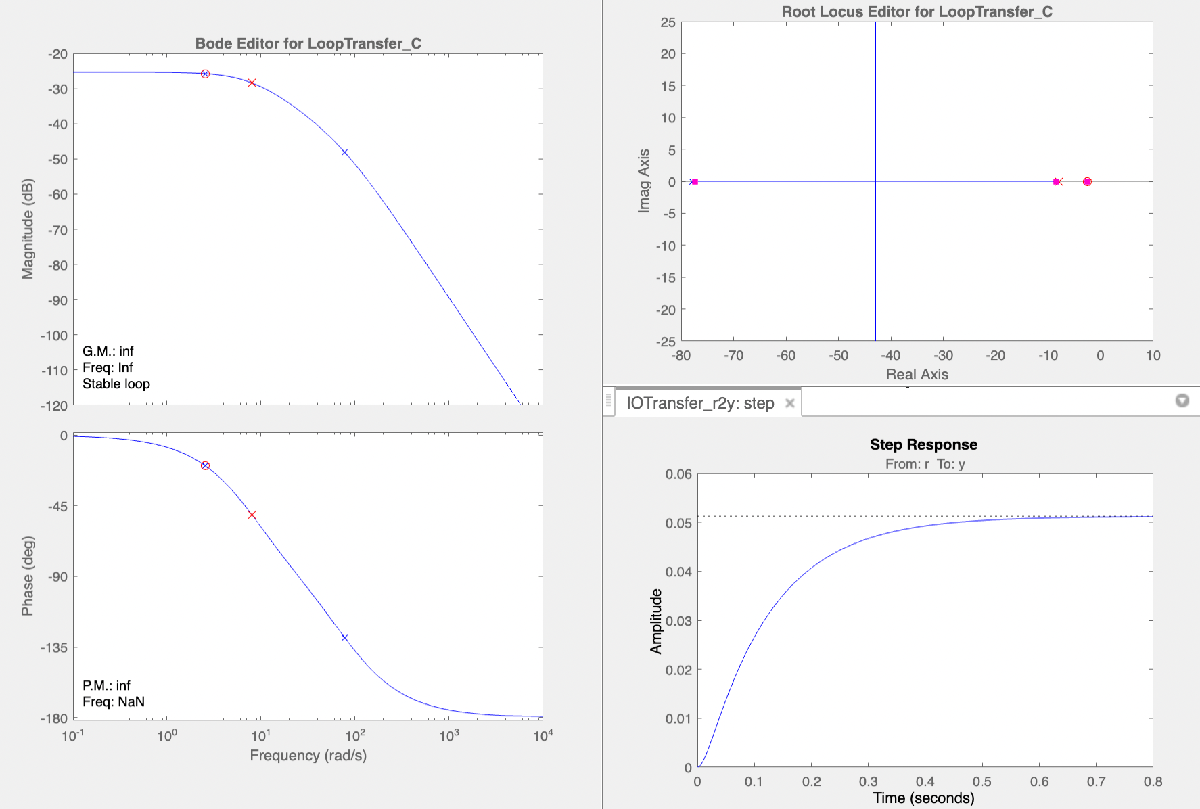

### Designing a LAG Compensator 

% From the computed transfer function, motortf, the system is a Type 1 system.

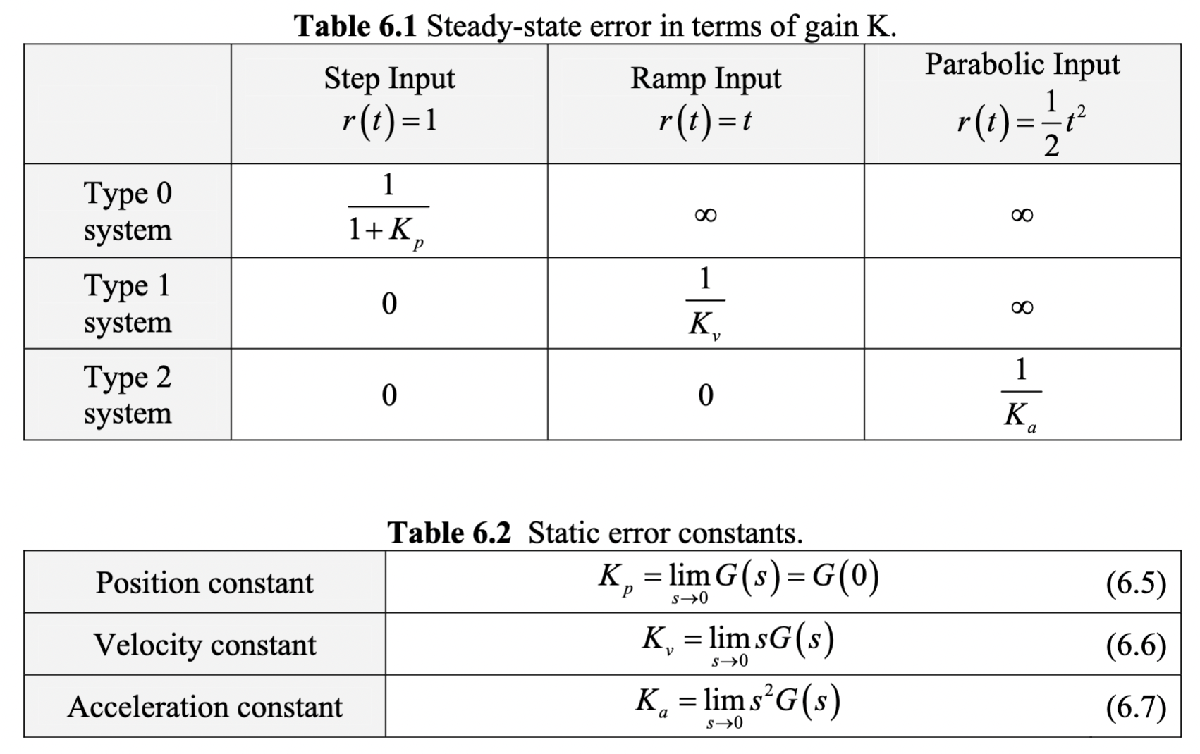

% Using the steady state error as the reference, the static error is
% constant is computed as follows. 

Kv= 200/80.4 % s appproaches 0, therefore s=0

Kv = 2.4876

elead= 1/Kv;
% Assume a value of Plag,
plag= 20; %**
zlag= (elead*plag)/SSE;

% the given transfer function for a lag compensator is:
num3= [1 zlag];
den3= [1 plag];
LGCtf= tf(num3, den3)

LGCtf =
 
  s + 8.04
  --------
   s + 20
 
Continuous-time transfer function.




numLGC= conv([200], num3);
denLGC= conv([1 80.4 200], den3);
motortfLGC= tf(numLGC, denLGC) % transfer function of the system compensated using a lag controller

motortfLGC =
 
           200 s + 1608
  -------------------------------
  s^3 + 100.4 s^2 + 1808 s + 4000
 
Continuous-time transfer function.



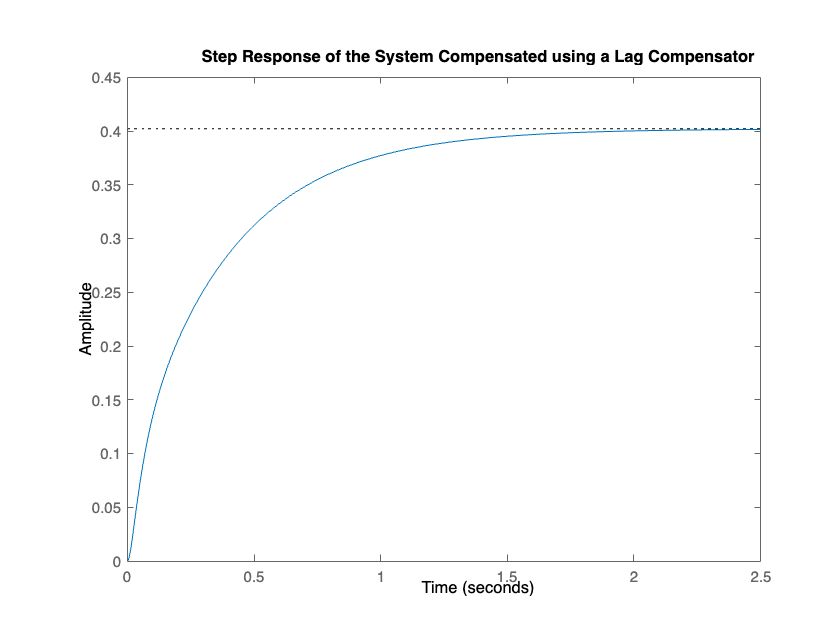


figure (2);
step(motortfLGC); title('Step Response of the System Compensated using a Lag Compensator');

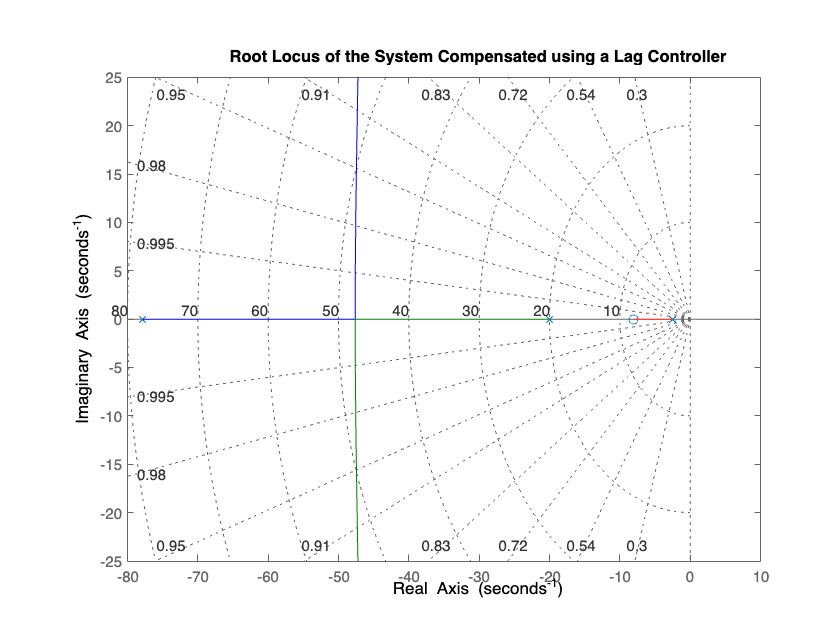

rlocus(motortfLGC); grid on; title('Root Locus of the System Compensated using a Lag Controller');

info_motorLGC= stepinfo(motortfLGC)

info_motorLGC = struct with fields:
         RiseTime: 0.7829
    TransientTime: 1.4391
     SettlingTime: 1.4391
      SettlingMin: 0.3618
      SettlingMax: 0.4014
        Overshoot: 0
       Undershoot: 0
             Peak: 0.4014
         PeakTime: 2.4366


[out2, t2]= step(motortfLGC);
SP= 1;
errorLGC= abs(SP-out2(end))

errorLGC = 0.5995

**== COMMENT:**

From the given step response info: 

- Settling Time= 1.5304 ... does not satisfy condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.5995 ... satisfied condition (<=1)

**== VISUALIZATION:**

Bode editor using the control system designer, sistool results:

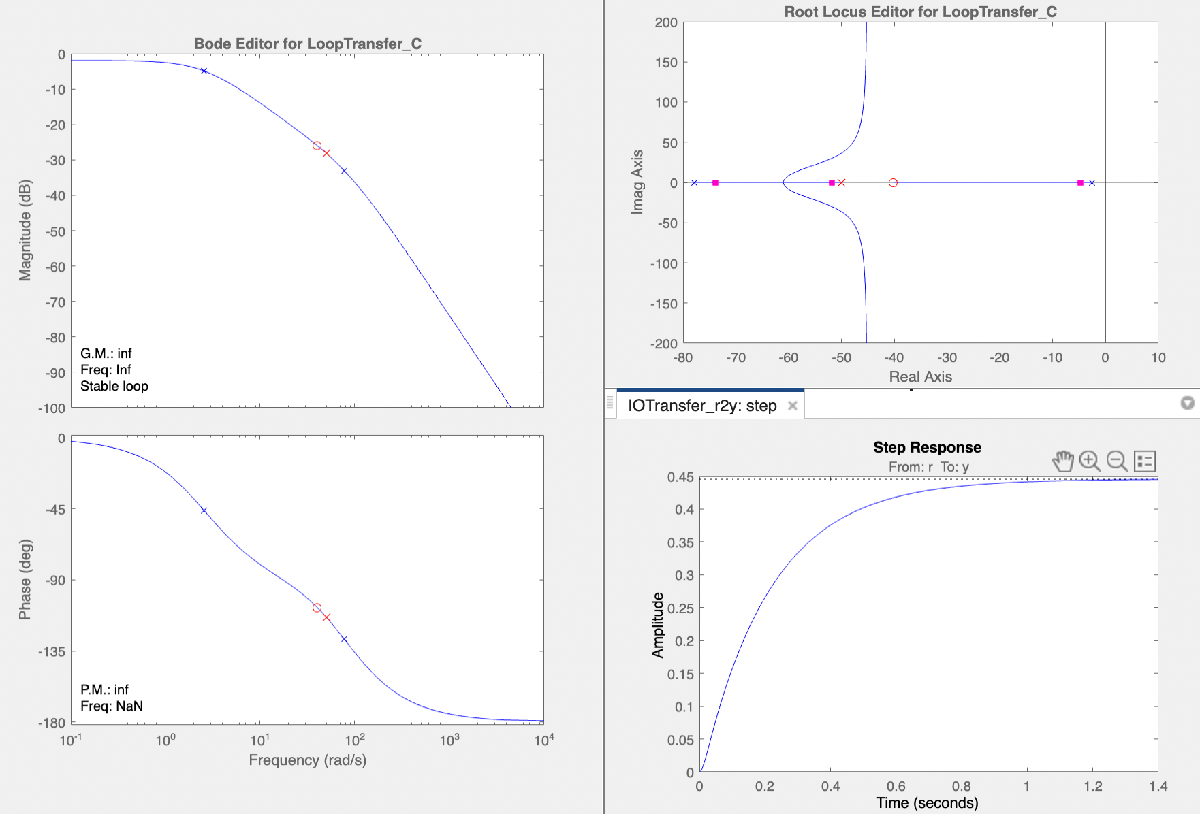

### Designing a LEAD-LAG Compensator 

% Cascading the lead and lag compensators, 

numf= conv(num2, num3);
denf= conv(den2, den3);
LDGCtf= tf(numf, denf) 

LDGCtf =
 
  0.168 s^2 + 1.782 s + 3.471
  ---------------------------
       s^2 + 28 s + 160
 
Continuous-time transfer function.



motortfLDGC= motortfCL*LDCtf*LGCtf

motortfLDGC =
 
           33.6 s^2 + 356.4 s + 694.1
  --------------------------------------------
  s^4 + 108.4 s^3 + 2611 s^2 + 18464 s + 32000
 
Continuous-time transfer function.



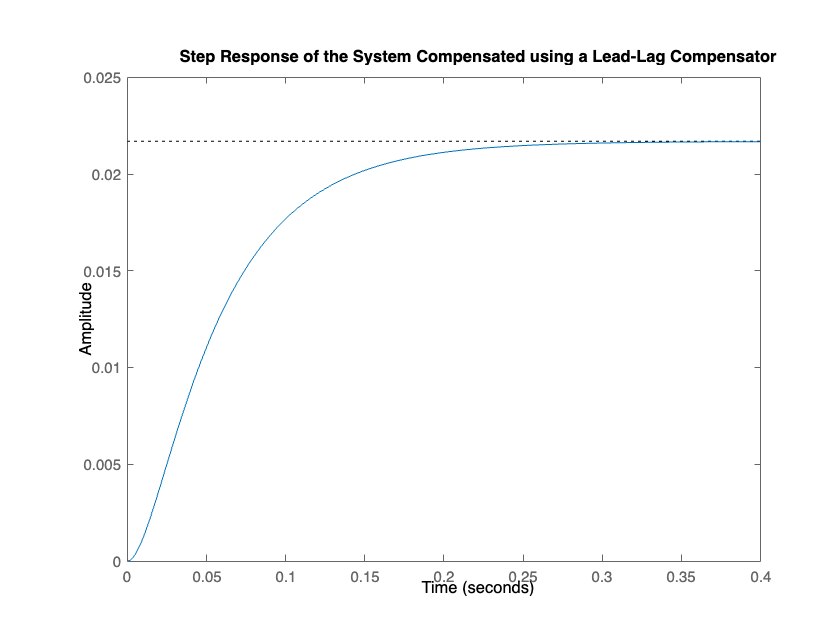

figure (3);
step(motortfLDGC); title('Step Response of the System Compensated using a Lead-Lag Compensator');

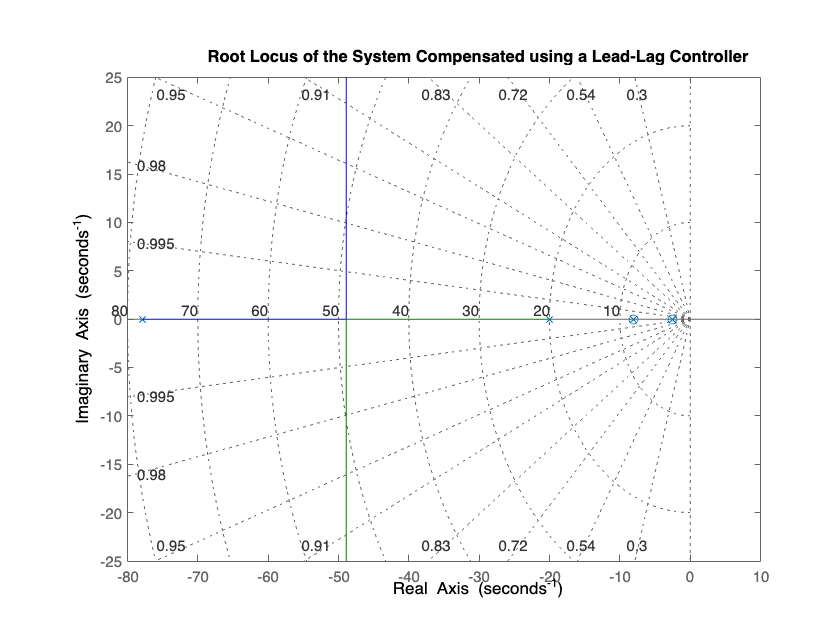

rlocus(motortfLDGC); grid on; title('Root Locus of the System Compensated using a Lead-Lag Controller');

info_motorLDGC= stepinfo(motortfLDGC)

info_motorLDGC = struct with fields:
         RiseTime: 0.1171
    TransientTime: 0.2144
     SettlingTime: 0.2144
      SettlingMin: 0.0195
      SettlingMax: 0.0217
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0217
         PeakTime: 0.4248


[out3, t3]= step(motortfLDGC);
SP= 1;
errorLDGC= abs(SP-out3(end))

errorLDGC = 0.9783

**== COMMENT:**

From the given step response info: 

- Settling Time= 0.2144... satisfied condition (<= 1 second)

- Overshoot= 0 ... satisfied condition (<= 5%)

- Steady-state error= 0.9783 ... satisfied condition (<=1%)

**== VISUALIZATION:**

Bode editor using the control system designer, sistool results:

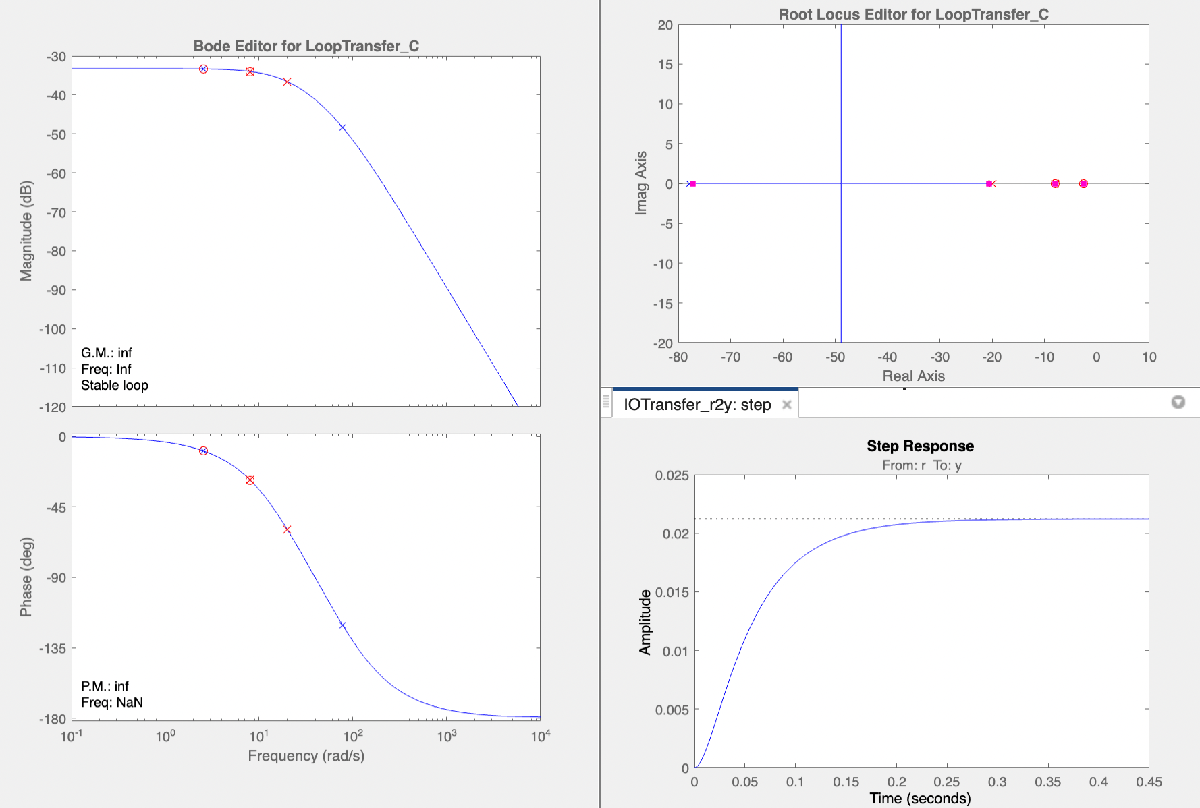

## Comparison of Data Through Visualization

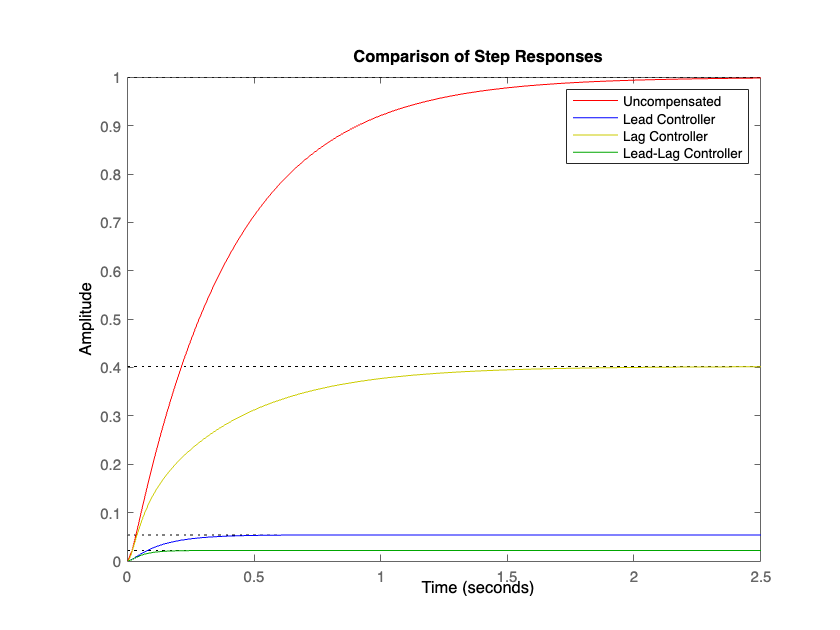

clf; 
figure (4);
step(motortfCL, 'r'); hold on;  
step(motortfLDC, 'b'); 
step(motortfLGC, 'y');  
step(motortfLDGC, 'g'); hold off; legend('Uncompensated','Lead Controller', 'Lag Controller', 'Lead-Lag Controller'); title ('Comparison of Step Responses')